# Signal re-sampling: up-sampling and down-sampling

## Introduction

Digital signals are sampled with different rates/ratios, e.g. in audio: 8000 (speech), 11025, 16000 (speech), 22050, 32000 (discretized FM radio), 44100 (CD disc), 48000 (DAB radio), 96000 (DSD), 192000, 384000, 764000 Hz. When we are adding signals in digital mixers, they must have the same sampling rate (sampling frequency). Therefore, before signal summation, signals sampled with lower ratio should be upsampled (quality is not lost) or signals sampled with higher ratio should be downsampled (significant quality degradation). For this reason, the second method is recommended. Typically, we increase or decrease the sampling ratio integer number of times, e.g. *K*-times up or *L*-times down. Doing a cascade of these two operations, first *K*-up than *L*-down, we change the sampling frequency *K*/*L*-times.   

## K-times up-sampling (interpolation)

A $K$-times up-sampler of digital signals (in other words $[1:K]$ - one input sample is replaced with $K$output samples) consists of:

- **digital expander** $[1:K]$, denoted as "$\uparrow K$", inserting $K-1$ zeros between each two signal samples, e.g. 2 zeros for $K=3$;

- **digital low-pass interpolation FIR filter** which shifts inserted zeros to the signal "waveform" and does not change the original signal samples (for this reason, the every $K$-th filter weight is equal to zero); the filter has 3-dB cut-off frequency equal to the half of the original sampling frequency $f_s/2$, the same time equal to the $1/K$-th of the new sampling frequency $(Kf_s)/2$, which is $K$-times higher.

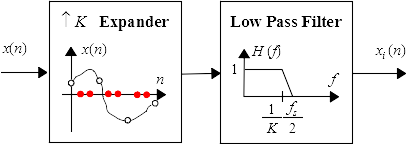

During filtering, multiplication of filter weights by inserted zeros should be avoided. The so-called poly-phase filter implementation has this nice feature. To understand/implement it, one should note that **during shifting the FIR filter weights by one sample among the signal with inserted zeros** (i.e. during weighted average calculation), only the $K$-th different filter weights, i.e. different filter polyphase components, are periodically multiplied with non-zero signal samples. For example, for $K=4$, the following filter weights are used during multiplication (**every 4-th, starting from**):

- **1-st pp component        2-nd pp component        3-rd pp component        4-th pp component  **

- from 0 **(0,4,8,12,...)**,         from 1 **(1,5,9,13,...)**,         from 2 **(2,6,10,14,...)**,       from 3 **(3,7,11,15,...)**;

- from 4 (4,8,12,16,...),       from 5 (5,9,13,17,...),       from 6 (6,10,14,18,...),      from 7 (7,11,15,19,...);

- from 8 (8,12,16,20,...),     from 9 (9,13,17,21,...),     from 10 (10,14,18,22,...),  from 11 (11,15,19,23,...);

- from 12 (12,16,20,24,...), from 13 (13,17,21,25,...), from 14 (14,18,22,26,...),  from 15 (15,19,23,27,...);

- ... continue ...

Thanks to this it is possible to:

- separately convolve the same poly-phase components of the signal and the filter (i.e. weights which are above in one column, starting from 0,1,2 and 3),

- and combine with interleaving samples of all poly-phase components of the obtained result, i.e. take one-by-one only the first, then the second, then the third, ... sample from each poly-phase filtration result.

**Analyze the Matlab code.** Run it, observe figures. Note that the interpolation filter is removing extra copies of signal spectrum which have occured after zero insertion. Check whether every `K`-th sample of the output is the same as corresponding input sample. Up-sample 8 kHz speech to 48 kHz. 

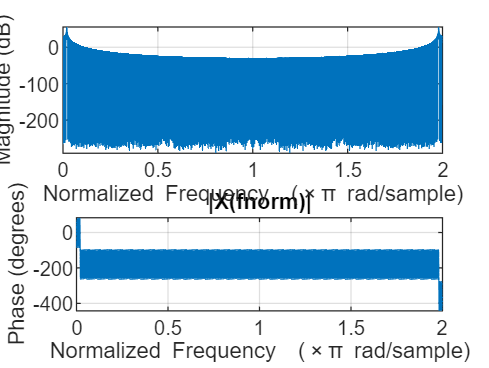

% K-times signal up-sampling

% Input - parameters and signal x
K=6; M=60; N=2*M+1; Nx=1200;               % K - up-sampling ratio, filter and signal lengths
x = sin(2*pi*(0:Nx-1)/100);                % signal to be up-sampled
% [x,fs]=audioread('speech.wav'); x=x(:,1)'; Nx = length(x);  % for further tests
R=rem(Nx,K); x = x(1:end-R); Nx = Nx-R;    % adjusting length to polyphase filtering

% Slow up-sampling (interpolation)
% one convolution of filter weights with zero-inserted signal 
xz = zeros(1,K*Nx);                        % # only zeros
xz(1:K:end) = x;                           % # copying signal samples
h = K*fir1(N-1, 1/K, kaiser(N,12));        % interpolation low-pass filter design                
yi = filter(h,1,xz);                       % signal filtering

figure; freqz(x,1,10000,'whole');  title('|X(fnorm)|');   % DFT spectrum of the signal x(n)

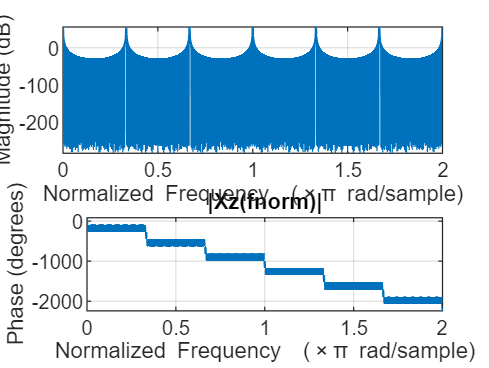

figure; freqz(xz,1,10000,'whole'); title('|Xz(fnorm)|');  % DFT spectrum of the signal xz(n)

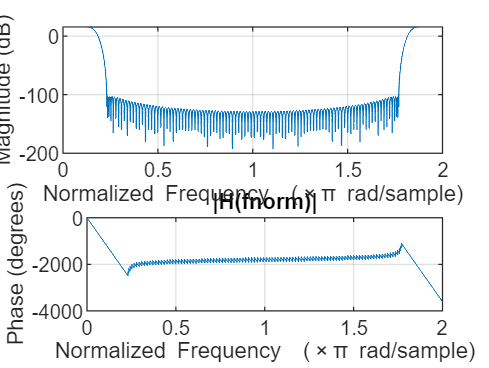

figure; freqz(h,1,10000,'whole');  title('|H(fnorm)|');   % DFT spectrum of the filter h(n) 

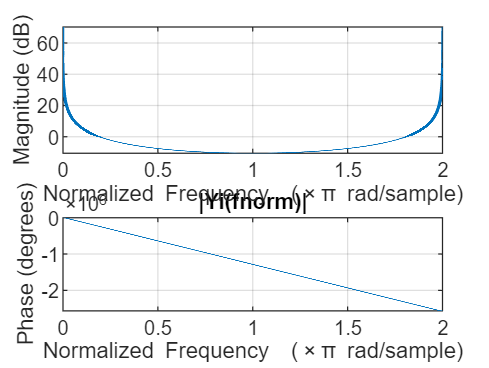

figure; freqz(yi,1,10000,'whole'); title('|Yi(fnorm)|');  % DFT spectrum of the signal yi(n)

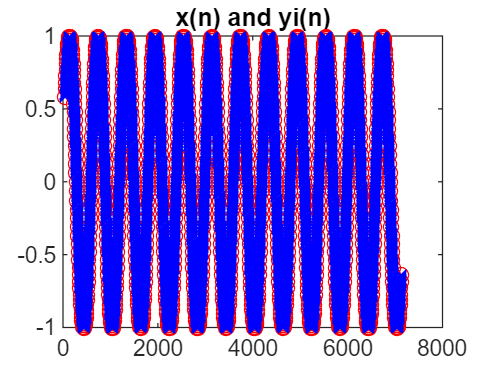


n = M+1:K:K*Nx-M; ni = N:K*Nx-(K-1);
figure; plot(n,x(M/K+1:Nx-M/K),'ro-',ni-M,yi(ni),'bx'); title('x(n) and yi(n)');

err1 = max(abs(x(M/K+1:Nx-M/K)-yi(ni(1:K:end)))),

err1 = 8.1954e-07


% Fast polyphase up-sampling (interpolation)
% K convolutions of original signal with K poly-phase filter weight sequences
% zeros are not inserted into the signal 
for k=1:K
    yipp(k:K:K*Nx) = filter( h(k:K:end), 1, x);
end
err2 = max(abs(yi-yipp)),

err2 = 2.2204e-16

## L-times down-sampling (decimation)

In digital signal $[L:1]$ down-sampler, the $L$ consecutive signal samples are replaced with one sample only. The down-sampler consists of:

- **digital low-pass decimation FIR filter** having stop-band beginning from the half of the new, target sampling frequency $f_s^{(new)}=f_s/L$, which is $L$-times lower than the original one $f_s$ (this is a consequence of the sampling theorem: $L$-times lower sampling frequency requires $L$-times more narrow signal frequency content/band);

- **digital reducer** $[L:1]$, denoted by "$\downarrow L$", leaving only each $L$-th signal sample.

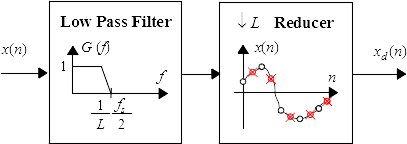

Since after filtration only each $L$-th sample is left, there is no sense to calculate samples to be removed. In fast poly-phase (PP) implementation of down-sampling they are not computed. This can be obtained by shifting forward the decimator filter weights directly by $L$ samples, not by only one. But in such case it is impossible to use fast convolution algorithms (for two vectors) exploiting the FFT:

`y=ifft( fft(xz) .* fft(hz) )`.

However application of fast convolution algorithm is possible when filter and signal samples are written in so-called poly-phase form. For example for $L=3$ and for the first output sample we have:


$$y(1)=x_1 h_1 + x_2 h_2 + x_3 h_3 + x_4 h_4 + x_5 h_5 + x_6 h_6 + x_7 h_7 + x_8 h_8 + x_9 h_9 +... =$$



$$=(x_1 h_1 + x_4 h_4 + x_7 h_7 + ...) + (x_2 h_2 + x_5 h_5 + x_8 h_8 + ...) + (x_3 h_3 + x_6 h_6 + x_9 h_9 + ...)$$


In such case, we can:

- perform, one-by-one, $L$ separate convolutions of $L$ corresponding signal & filter polyphase components (in our example sequences of samples starting from the 1-st, 2-nd, 3-rd sample),

- obtain $L$ different resultant vectors,

- add their corresponding elements, i.e. $L$ the 1-st, $L$ the 2-nd, $L$ the 3-rd,...

**Analyze the Matlab code.** Run it, observe figures. Note that the decimation filter is leaving only $1/L$ of the signal frequency band, no more (it is a significant difference in comparison to interpolation filter having 3-dB decrease for the frequency $1/K$: at present we require many dBs at the frequency $1/L$).  Down-sample 44.1 kHz music to 11.025 kHz.

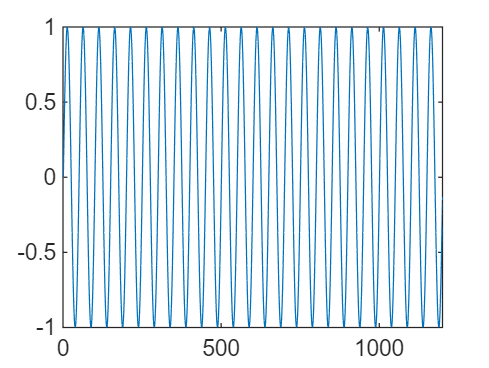

% L-times signal down-sampling

% Input - parameters and signal x
L=5; M=60; N=2*M+1; Nx=1200;                  % L - down-sampling ratio, filter and signal lengths
x = sin(2*pi*(0:Nx-1)/50); plot(x);           % signal to be down-sampled

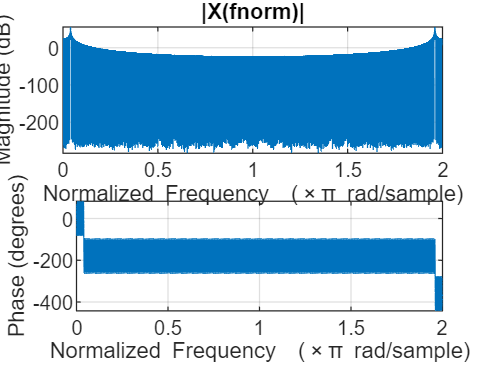

% [x,fs]=audioread('music.wav'); x=x(:,1)'; Nx = length(x);  % for further tests
R=rem(Nx,L); x = x(1:end-R); Nx = Nx-R;       % adjusting length to polyphase filtering

% Slow down-sampling (decimation)
% one convolution of filter weights with signal samples, then decimation 
g = fir1(N-1, 1/L - 0.1*(1/L),kaiser(N,12));  % decimation low-pass filter design
y = filter(g,1,x);                            % signal filtering
yd = y(1:L:end);                              % signal decimation (only every L-th sample is left)

figure; freqz(x,1,10000,'whole');  title('|X(fnorm)|');   % DFT spectrum of the signal x(n)

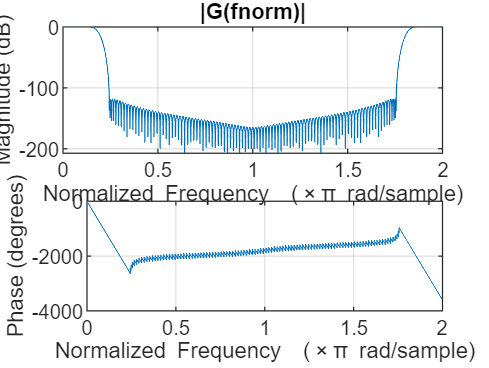

figure; freqz(g,1,10000,'whole');  title('|G(fnorm)|');   % DFT spectrum of the filter g(n) 

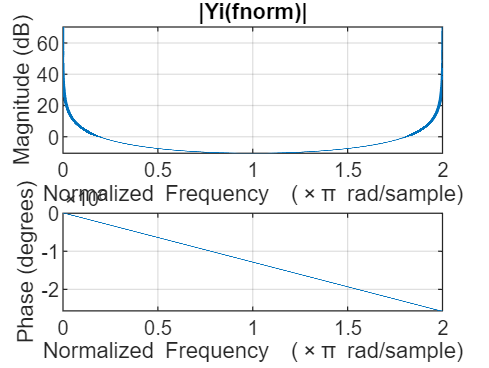

figure; freqz(yi,1,10000,'whole'); title('|Yi(fnorm)|');  % DFT spectrum of the signal yi(n)

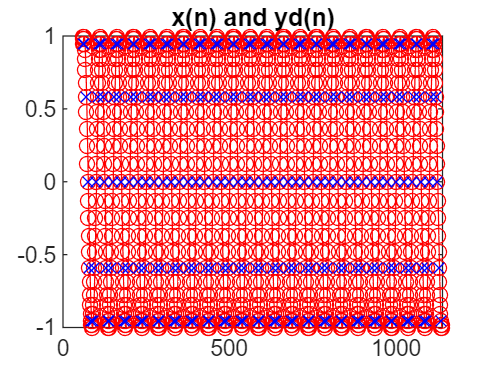


n = M+1:Nx-M; nd = (N-1)/L+1:Nx/L;
figure; plot(n,x(n),'ro-',n(1:L:end),yd(nd),'bx'); title('x(n) and yd(n)');

err1 = max(abs(x(n(1:L:end))-yd(nd))),

err1 = 1.0320e-06


% Fast polyphase down-sampling (decimation)
% L convolutions of PP components of original signal and filter weights
% samples to be removed are not calculated 
x = [ zeros(1,L-1) x(1:end-(L-1)) ];
ydpp = zeros(1,Nx/L);
for k=1:L
    ydpp = ydpp + filter( (g(k:L:end)), 1, x(L-k+1:L:end) );
end
err2 = max(abs(yd-ydpp)),

err2 = 6.6613e-16

## K/L-times signal re-sampling

Very often not integer value up-sampling or down-sampling is required. For example:

- changing signal frequency from 32 kHz to 48 kHz requires 3-times ($\uparrow 3 \times$) up-sampling followed by 2-times ($\downarrow 2 \times$) down-sampling,

- changing signal frequency from 44.1 kHz to 48 kHz requires ($\uparrow 160 \times$) up-sampling followed by ($\downarrow 147 \times$)  down-sampling (approximately: $\left[ \uparrow 37 \times, \;\; \text{then} \downarrow 34 \times \right] $ or $\left[ \uparrow 12 \times, \;\; \text{then} \downarrow 11 \times \right] $; use the following Matlab code for finding required  `UP,DOWN`  numbers:` tol=0.01, 0.001, 0.0001; [UP,DOWN]=rat(48000/44100,tol);`).

**Important**:

- The UP-sampling is always first in the cascade of up-sampling and down-sampling since in the DOWN-sampling operation the signal bandwidth is reduced in un-recoverable way.

-  In a digital frequency UP-DOWN conversion system the following operations are performed: first the expander $\uparrow K \times$, then an interpolation filter followed by a decimation filter, finally reducer $\downarrow L \times$. Because two low-pass filters are used in a cascade, therefore only one of them with more narrow pass-band can be used: the $1/K$ low-pass filter of the interpolator albeit $1/L$ low-pass filter of the decimator.

- When a frequency conversion ratio, UP or DOWN, is very high, it is more computationally efficient to do re-sampling in a cascade of simpler steps, e.g. $\uparrow 120 \times =(\uparrow 4 \times) +(\uparrow 5 \times)  + (\uparrow 6 \times)$.  In such solution significantly shorter filters can be used because their bandwidths are wider. 

**Write the Matlab code.** Resample some music from 44100 kHz to 32000 kHz. From two low-pass filters, for interpolation and decimator, use only one. Apply cascade of simpler re-sampling steps - with lower re-samplin ratios. 

% Your task and your pleasure 